% set index = 2 (sum PHI) in MC_import
MC_import

ans =     13     1


ans =     15   468


ans =     16    14


ans =     14     1


ans =     16     5


ans =     18     3



exp_data = readtable("Subjective score.xlsx", 'Sheet','Diff Intervention');
exp_solv = readtable("Subjective score.xlsx", 'Sheet','The number of Responses');


member = 1:20;
member([11, 14]) = [];
member(15) = [];

exp_solv = table2array(exp_solv(member, 2));

% active - control - passive
Excitement = table2array(exp_data(member, 3:5));
Efforts = table2array(exp_data(member, 6:8));
Concentration = table2array(exp_data(member, 9:11));
Tiredness = table2array(exp_data(member, 12:14));
Irritation = table2array(exp_data(member, 15:17));
Boring = table2array(exp_data(member, 18:20));
Annoying = table2array(exp_data(member, 21:23));


**Easy - Moderate correlation**

member2 = 1: 18;
member2(15) = [];

b = Excitement + Efforts + Tiredness;
c = Irritation + Boring;

[s, p]  =corr(b(:, 2)-b(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
[s, p]  =corr(c(:, 2)-c(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.1248

p = 0.6331


scatter(b(:, 2)-b(:, 1), mean(control_PHI(member2, time1:time2)...

s = 0.6229

p = 0.0076

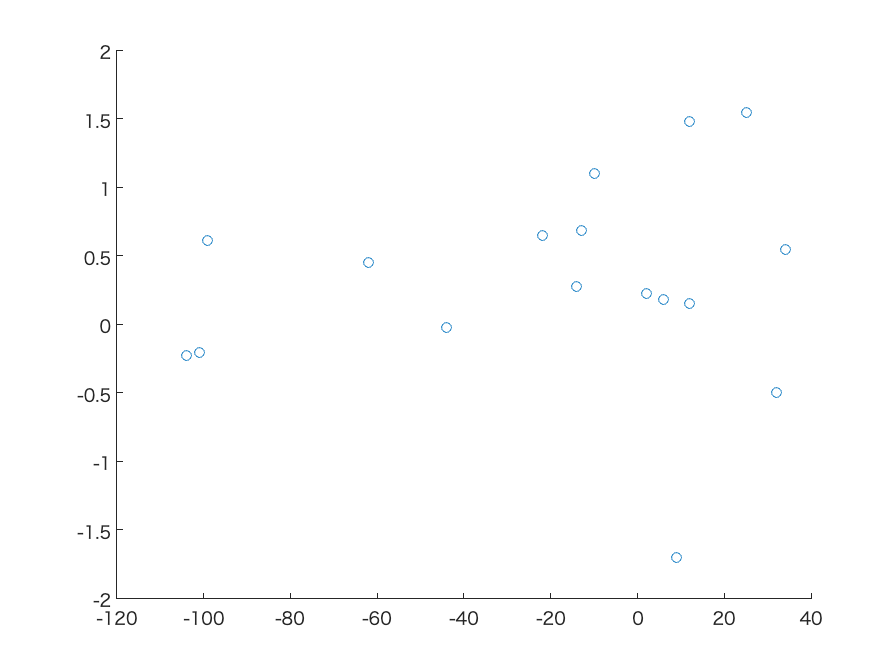

    - active_PHI(member2, time1:time2),2))
scatter(c(:, 2)-c(:, 1), mean(control_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

**Difficult - Moderate correlation**

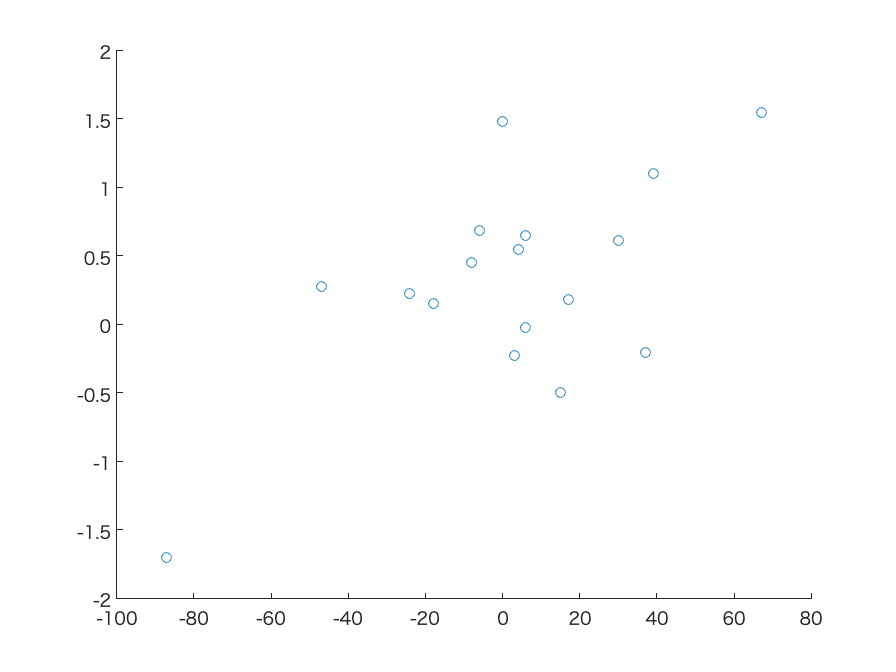

b = Excitement + Efforts + Tiredness + Concentration;

c = Irritation + Boring + Annoying;

[s, p]  =corr(b(:, 3)-b(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
[s, p]  =corr(c(:, 3)-c(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))



s = 0.4330

p = 0.0825

scatter(b(:, 3)-b(:, 1), mean(passive_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

s = -0.5305

p = 0.0285

scatter(c(:, 3)-c(:, 1), mean(passive_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

**Easy - Moderate correlation : each condition**

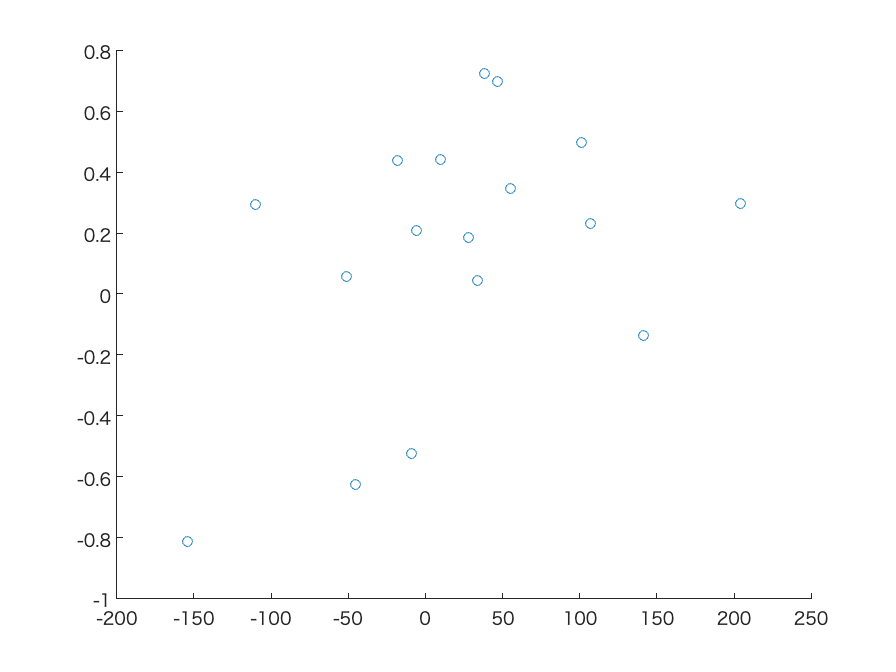

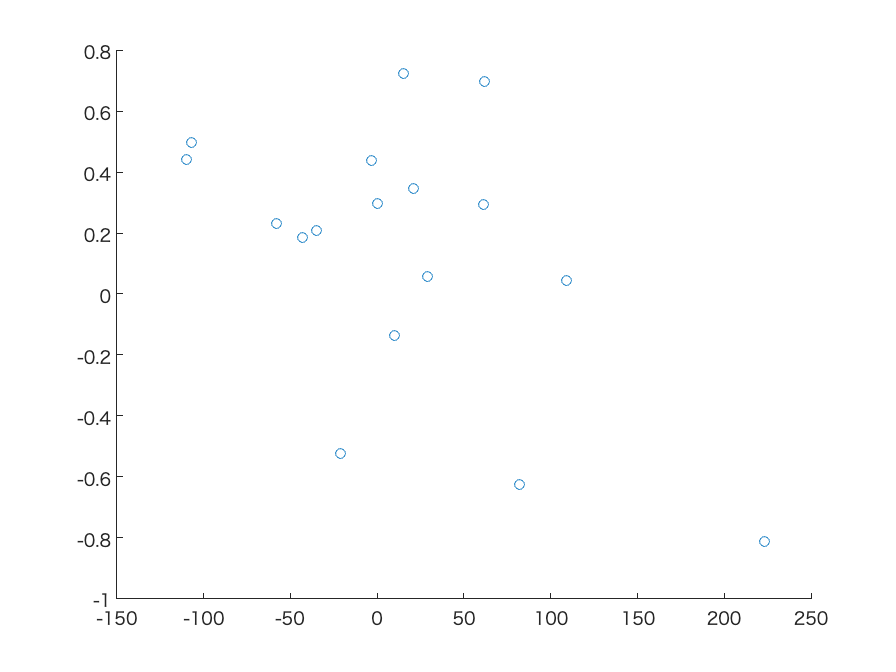

pvalue = zeros(14, 1);
corr_value = zeros(14, 1);


[s, p]  =corr(Excitement(:, 2)-Excitement(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(1) = p;
corr_value(1) = s;

[s, p]  =corr(Efforts(:, 2)-Efforts(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.0414

p = 0.8747

pvalue(2) = p;
corr_value(2) = s;

[s, p]  =corr(Concentration(:, 2)-Concentration(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.0558

p = 0.8315

pvalue(3) = p;
corr_value(3) = s;

[s, p]  =corr(Tiredness(:, 2)-Tiredness(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.2498

p = 0.3336

pvalue(4) = p;
corr_value(4) = s;

[s, p]  =corr(Irritation(:, 2)-Irritation(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.1954

p = 0.4523

pvalue(5) = p;
corr_value(5) = s;

[s, p]  =corr(Boring(:, 2)-Boring(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.3453

p = 0.1746

pvalue(6) = p;
corr_value(6) = s;

[s, p]  =corr(Annoying(:, 2)-Annoying(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.5652

p = 0.0181

pvalue(7) = p;
corr_value(7) = s;

**Difficult - Moderate correlation : each condition**

[s, p]  =corr(Excitement(:, 3)-Excitement(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.2902

p = 0.2585

pvalue(8) = p;
corr_value(8) = s;

[s, p]  =corr(Efforts(:, 3)-Efforts(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(9) = p;
corr_value(9) = s;

s = 0.4426

p = 0.0752


[s, p]  =corr(Concentration(:, 3)-Concentration(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(10) = p;
corr_value(10) = s;

s = 0.2122

p = 0.4137


[s, p]  =corr(Tiredness(:, 3)-Tiredness(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(11) = p;
corr_value(11) = s;

s = 0.1736

p = 0.5053


[s, p]  =corr(Irritation(:, 3)-Irritation(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(12) = p;
corr_value(12) = s;

s = 0.3613

p = 0.1542


[s, p]  =corr(Boring(:, 3)-Boring(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(13) = p;
corr_value(13) = s;

s = -0.4030

p = 0.1087


[s, p]  =corr(Annoying(:, 3)-Annoying(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))
pvalue(14) = p;
corr_value(14) = s;

s = -0.5166

p = 0.0337


T = table(type_names, item_names, corr_value, pvalue);

%writetable(T, "each_item_correlation_" + num2str(interval) + ".csv");

s = -0.3893

p = 0.1225